# Exercice #5 : TR Module Design

clear;
clc;
format shortEng;

%---------------------------------------------------------------------------------------------------
% GOALS : 
% In this exercise, we will focus on the design of the TR module
% We are using an 8x8 antenna and want to provide the ability to steer the
% beam so that each radiating element needs to be controlled individually.
% TR module will provide the proper amplification but also phase shift and
% attenuation capabilities to adjust relative phase on each element and
% also enable calibration of the antenna array
% TR module generally provide TX and RX specific capabilities. TX will
% require a Power Amplifier (PA) that may exhibit non linearities that
% could impact the performances and RX will mainly require attention on the
% LNA so that the Noise Figure of the receiver does not degrade detection
% performances.
% A "Common Leg" will often be shared between TX and RX and it will
% typically include an amplifier, phase shifter and attenuator.
% TR module are subject to serious constraints in terms of size, heat
% dissipation and maintainability and are built typically using MMIC's
%---------------------------------------------------------------------------------------------------

To illustrate what a typical TR module may look like, we will refer to this article.

- [https://www.microwaves101.com/encyclopedias/transmit-receive-modules](https://www.microwaves101.com/encyclopedias/transmit-receive-modules)

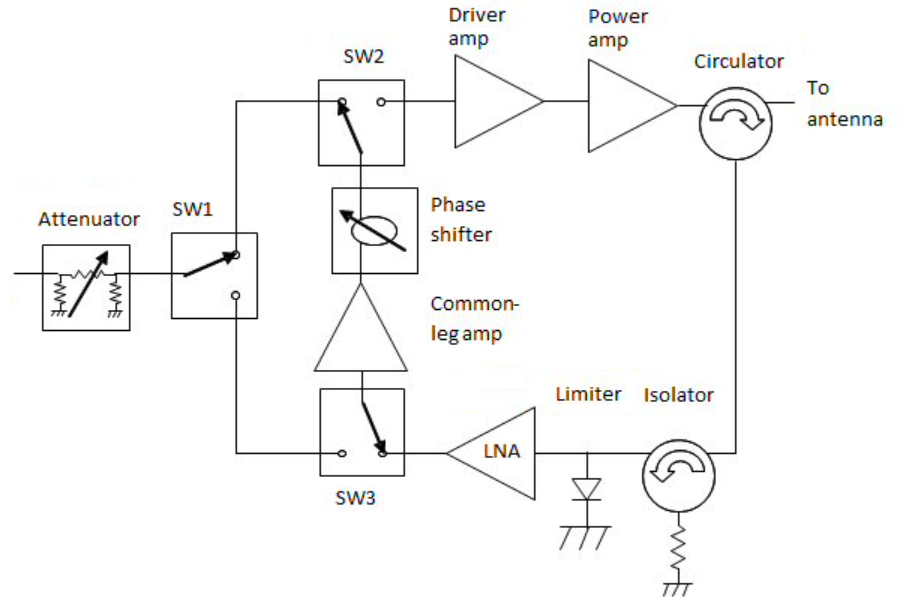

We will notice a few points : 

- TX Amplification is realized in several steps : common leg amplifier + driver amplifier + Power Amplifier

- RF Switches are used to switch from TX to RX modes

- Circulators are used to avoid high power from TX to leak to very sensitive RX chain.

**NOTE : **we will place the attenuator in the common leg in our design and the diagram above will require a slight modification...

## Fundamental informations

- Physical constants

c       = physconst('LightSpeed');      % speed of light
k       = physconst('Boltzmann');       % Boltzmann's constant (compute noise power density)
T       = 290.0;                        % Temperature (expressed in Kelvin)
fc      = 2.4e9;     % center frequency
lambda  = freq2wavelen(fc,c)            % 

## Transmitter

#### First steps with RF Budget Analyzer

%---------------------------------------------------------------------------------------------------
% EXERCISE
% 
% We will now use the RF Budget Analyzer app to build the Transmitter leg
% 
% Goal : create the TX RF Chain, export to Simulink and verify the total
% gain is as expected. We will also include realistic impairmenets on the
% amplifier (focus on non-linearity for the TX subsystem)
%---------------------------------------------------------------------------------------------------

- `T/R Module in TRANSMIT State`

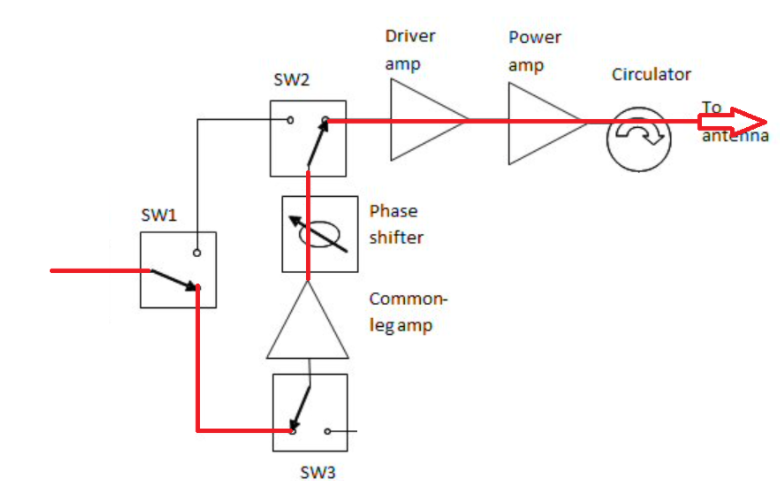

TX amplifier is split in 3x stages and we will run a quick analysis first, before revisiting the overall TX chain, including switches and circulators.

- `Open the RF Budget analyzer App`

rfBudgetAnalyzer

#### 1 - Specify System Parameters

- Waveform generator provides 3dBm (2mW) per channel

- 1MHz (1us pulseWidth) is used to compute the noise floor

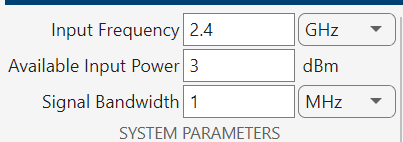

We will start with an "ideal" model (ignore non-linearities, perfect impedance matching) and will gradually add real-world impairments in our model...

- Add 3x amplifiers

%---------------------------------------------------------------------------------------------------
% Multi-stage RF amplifiers consist of multiple amplification circuits linked in series, 
% each contributing to the overall gain. 
% This configuration allows for greater flexibility in achieving : 
% - higher gain levels
% - improved bandwidth 
% - enhanced linearity 
% The multi-stage design can also provide better control over noise as each stage can be optimized to minimize its contribution to the overall noise figure.
% One of the key benefits of multi-stage amplifiers is their adaptability to a wide range of applications, 
% However, this complexity comes with increased cost, a larger physical footprint, 
% and potentially higher power consumption.
% Additionally, designing multi-stage amplifiers requires careful consideration of stability and matching between stages to prevent oscillations and ensure optimal performance.
%---------------------------------------------------------------------------------------------------

AMP1 | G1 = 12dB - NF = 3 dB - OIP3 = INF

AMP2 | G2 (DRIVE) = 25dB - NF = 5 dB - OIP3 = INF

AMP3 | G3 (HPA) = 13 dB - NF = 0dB - OIP3 = INF 

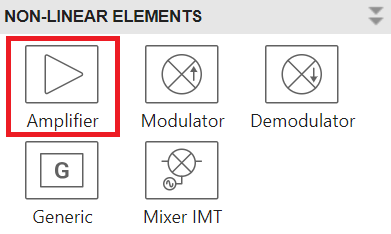

- Verify the  overall budget in terms of gain and SNR

- What happens id G2 (NF = 5dB) is placed before G1 (NF = 3dB)

- What is the level at AMP3 input ?

- What happens if the OIP3 of the HPA is set to 38dBm ?

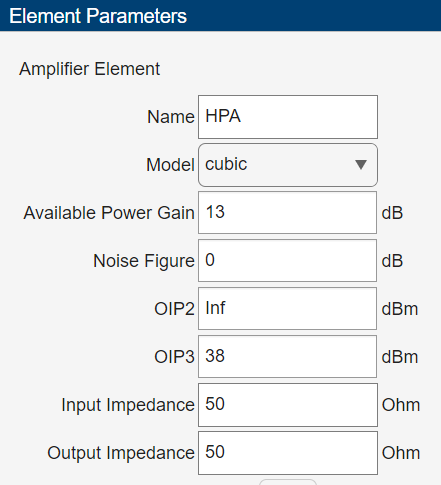

`tip : use the plot power characteristics (Pout vs. Pin) to answer this question `

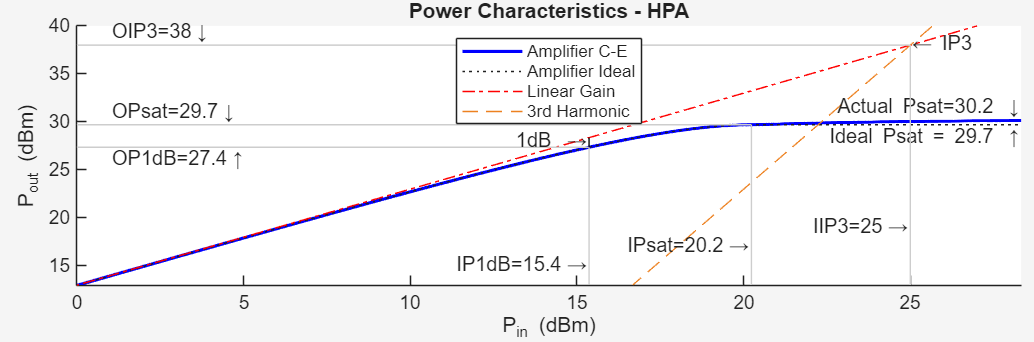

We will now open the ideal TX chain that has been pre-built : 

rfBudgetAnalyzer("TX_Budget_Ideal.mat")

The overall TX chain should look like : 

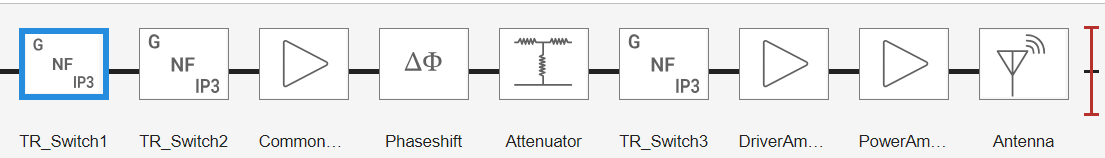

- Discuss the "static" budget (FRIIS) using ideal components : 

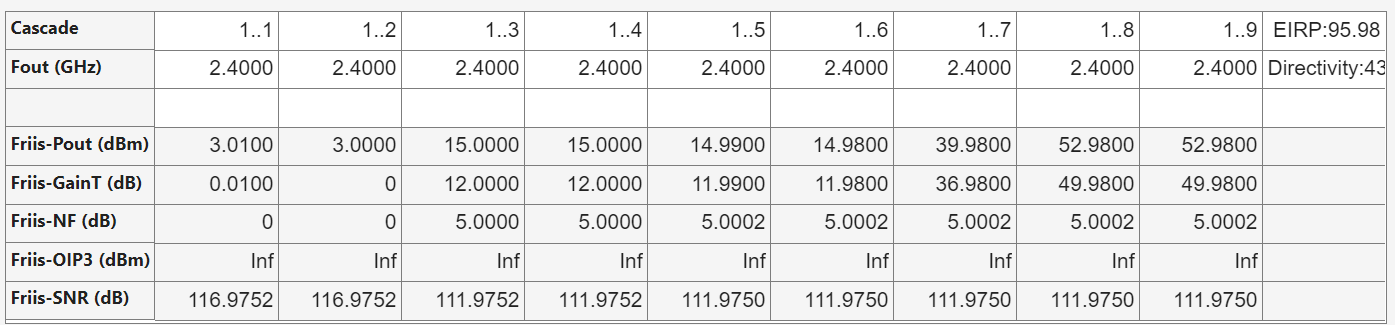

### Export to RF Blockset Model :

- RF Budget Analyzer provides the ability to export the design to Simulink to enable verification and/or integration with the system level model (waveform generation, antenna, radar signal processing, ...)

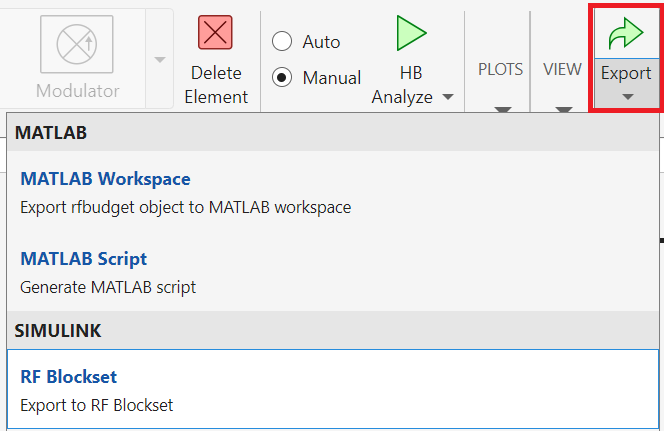

%---------------------------------------------------------------------------------------------------
% MAKING THE MODEL MORE REALISTIC
%
% Our current model is using 'perfect' componenents and we would like to
% make it more realistic and mimic the behavior described in the different
% components datasheets.
% 
% To achieve this goal, we will now use S-parameters to describe the
% behavior of our circulator, define an IP3 for the common leg amplifier
% and model our Power Amplifier using an AM/PM table (capture non
% linearities)
%
% EXERCISE :
% 
% Make the modifications described beow to the RF budget you have just created
%
%---------------------------------------------------------------------------------------------------

- Use the TX_Circulator S3P file to describe the frequency domain behavior of the circulator :

`tip : make sure Input Port = 1 & Output Port = 2 (a circulator has more than 2x ports...hence the S``3``p filename)`

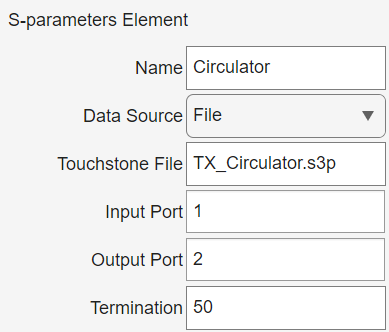

`Note : you can visualize S parameters for the component by clicking <``Plot>S parameters plot``>`

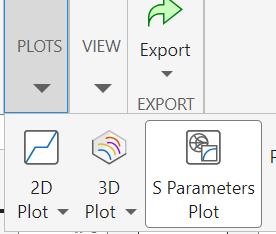

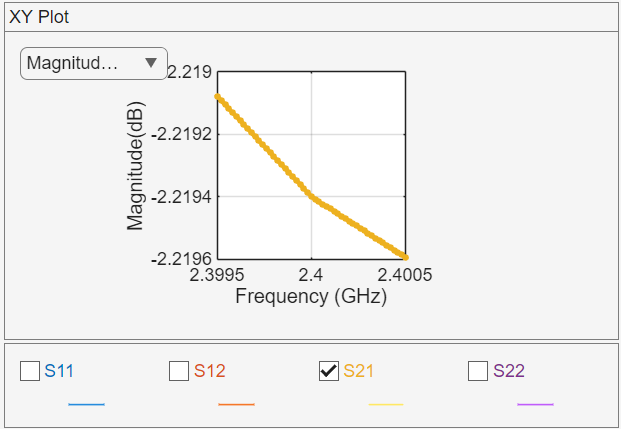

`Question : What is the Insertion loss of this circulator at fc = 2.4GHz ?`

- Define CommonLegAmp with its NF (5dB) nd OIP3 (38dBm)

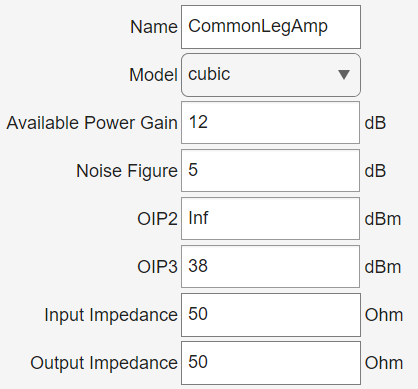

- Use the "Plot Power Chracteristics" to visualize the amplifier's response : 

- Use an AM/AM AM/PM table to specify Power Amplifier non-linearities

%% Power amplifier AM-AM/AM-PM characteristics
inAM  = [0.1 1  2  3   4   5]';
outAM = [5 50 85 110 115 120]';
outPM = [0 1  2  10  20  50]';
ampmTablePA = [10*log10(inAM)+30 ...
    10*log10(outAM)+30 ...
    outPM];

figure; 

subplot(2,1,1)
plot(ampmTablePA(:,1), ampmTablePA(:,2));
title('Amplifier AM-AM/AM-PM Characteristic')
xlabel('Pin (dBm)'); ylabel('Pout (dBm)');

subplot(2,1,2)
plot(ampmTablePA(:,1), ampmTablePA(:,3));
xlabel('Pin (dBm)'); ylabel('Phase (deg)');

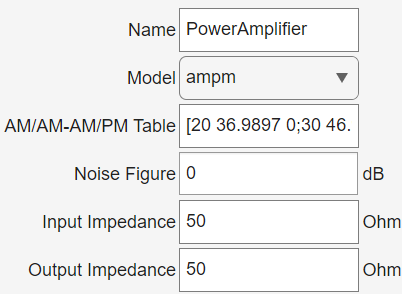

`Note:` HB and FRIIS comparison may indicate we are operating in a linear mode vs. non linear mode.

`Solution : `

`We have created an enhanced model based on the one we have just created :`

rfBudgetAnalyzer("TX_Budget_Datasheet.mat")

#### Please observe the following : 

- s3p file (circulator)

- OIP3 : Common Leg AMP

- AM/PM Table is used for Power Amplifier

### Export to RF Blockset Model :

- Explore S parameters

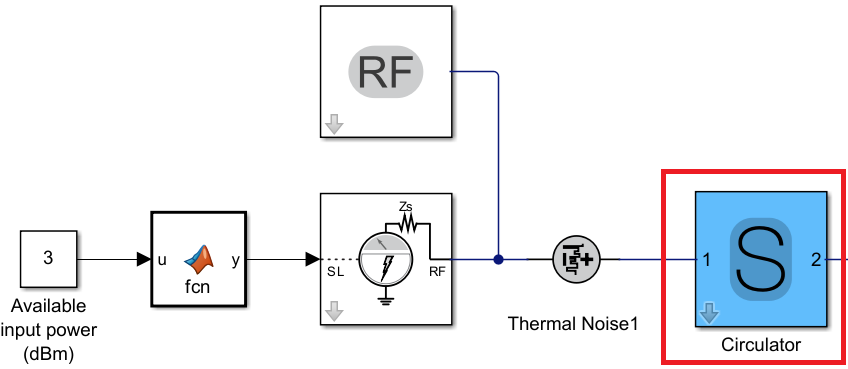

- In the visualization tab, select S21

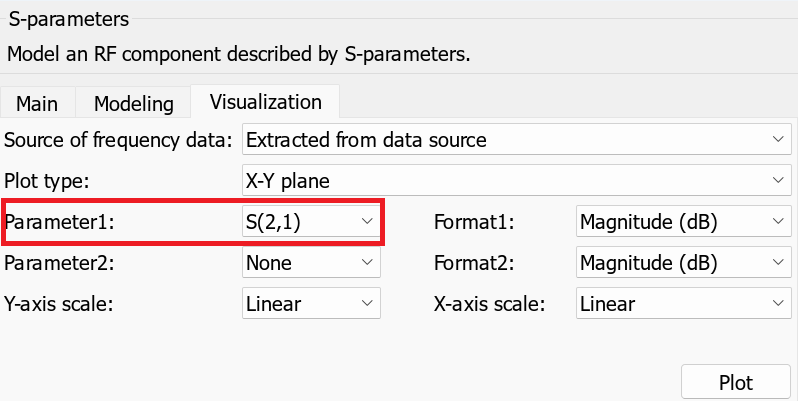

- press Plot

- Measure the loss introduced by the circulator at 2.4 GHz

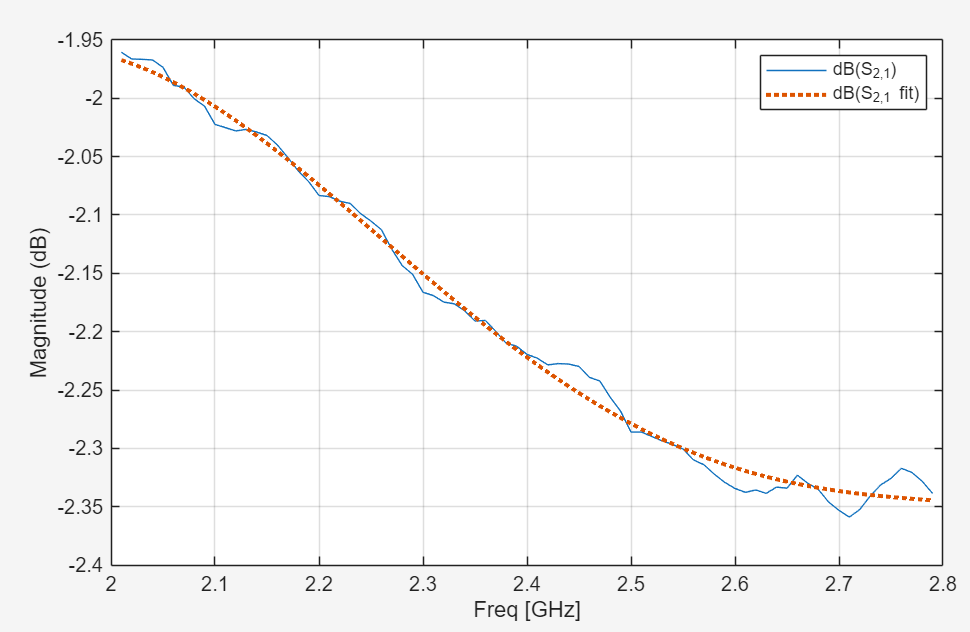

- Measure the power at different steps

open_system("TX_Datasheet_Model.slx")

RECEIVER (Optional)

#### Start with RF Budget Analyzer

%---------------------------------------------------------------------------------------------------
% EXERCISE
% 
% Same as above, except we will focus on LNA and its NF contribution
%
%---------------------------------------------------------------------------------------------------

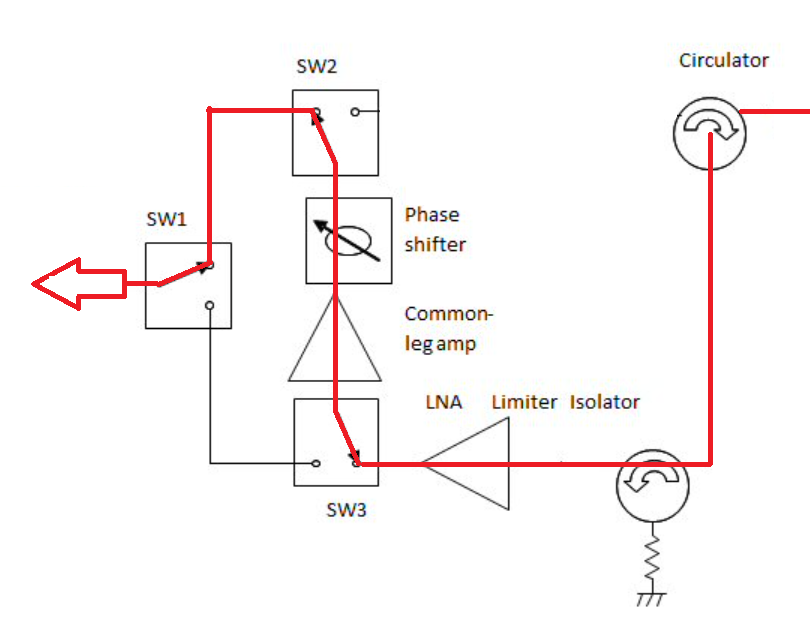

`Solution : `

rfBudgetAnalyzer("RX_Budget_Datasheet.mat")

## PUTTING IT ALL TOGETHER

- Verifying RF behavior

%---------------------------------------------------------------------------------------------------
% EXERCISE
% 
% We will now build the details model of the TR module by combining our TX
% and RX chains
% 
% For the sake of time, the model is provided and we will now perform
% measurements using this model
%
%---------------------------------------------------------------------------------------------------

#### Simulation Model

open_system('TR_Module_Datasheet.slx')

`Observations :`

- `Switch between TX and RX and make observations, especially related to isolation between TX and RX`